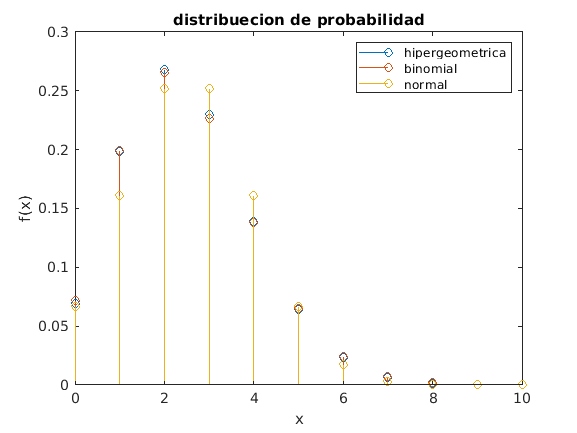

clear
clc
x=0:1:10;
N=1000;
k=100;
n=25;
r1=hygepdf(x,N,k,n);
p=k/N;
r2=binopdf(x,n,p);
q=(1-p);
r3=normpdf(x,n*p,sqrt(n*p*q));
stem(x,r1);
title('distribuecion de probabilidad')
xlabel('x')
ylabel('f(x)')
hold on
stem(x,r2)
stem(x,r3) 
legend('hipergeometrica','binomial','normal')
hold off